Lab3

uppgift 1)

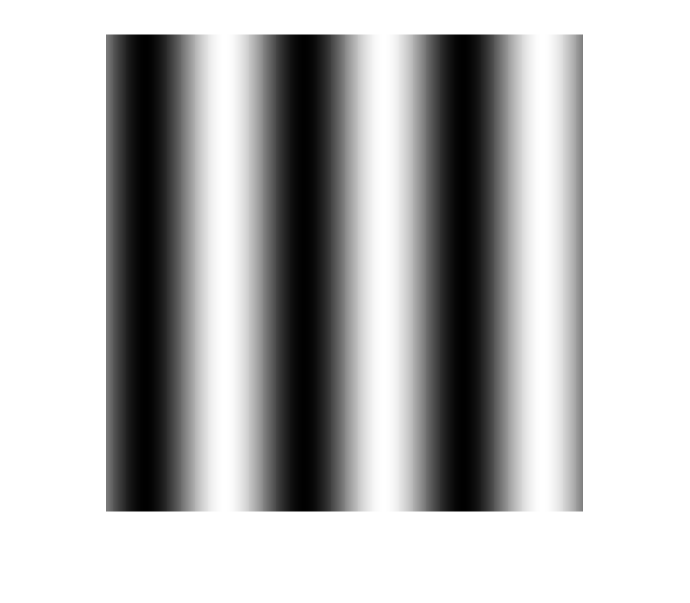

clear
clf

colormap('gray');
for r=1:512
    	    for c=1:512
        	    B1(r,c)=uint8(128-127*sin(2*pi*3*c/512));
        	    B2(r,c)=uint8(128-127*sin(2*pi*45*c/512));
                B3(r,c)=uint8(128-127*sin(2*pi*90*c/512));
    	   end
end
	figure(1); 
    imshow(B1); 

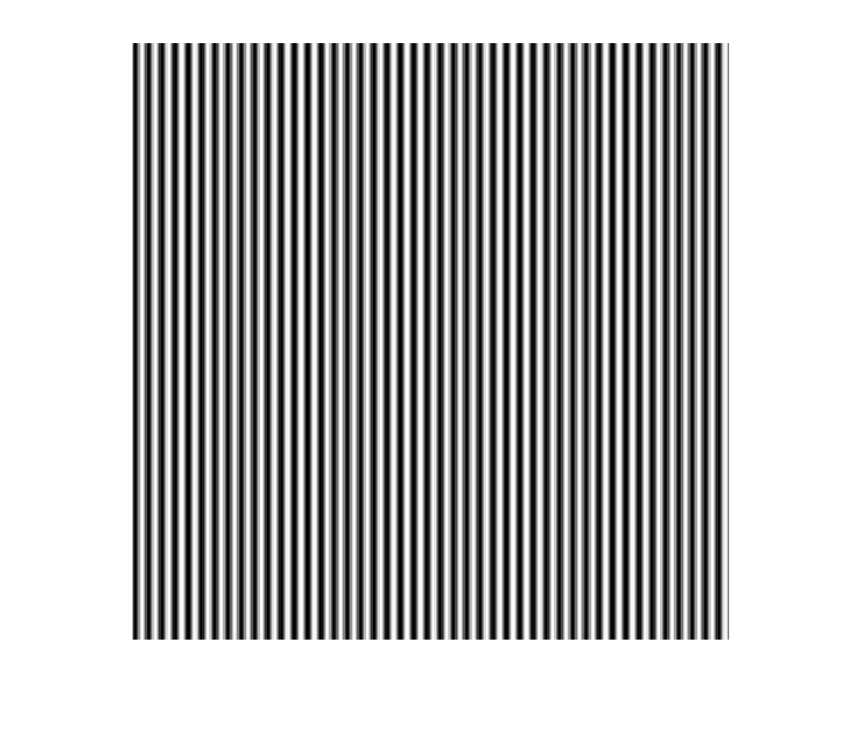

    figure(2); 
    imshow(B2);

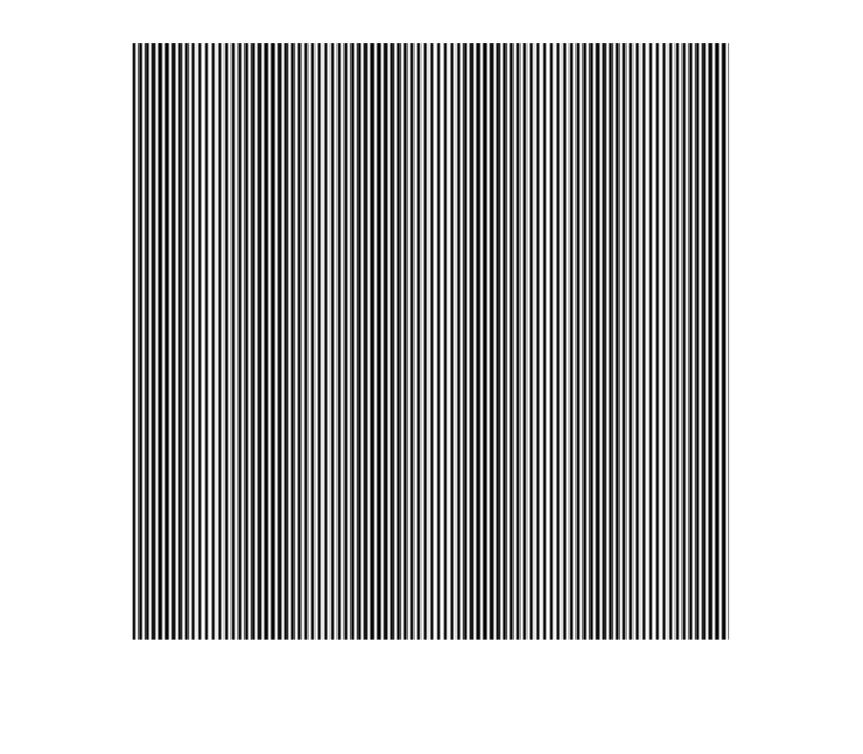

    figure(3);
    imshow(B3);

uppgift 2)

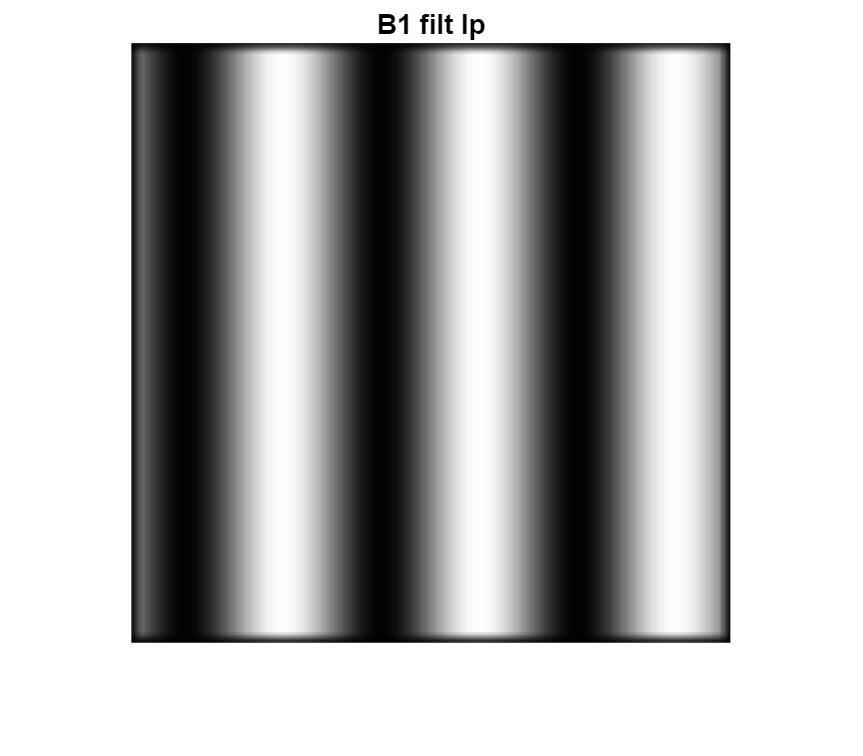

clf


h_lp = (1/100)*ones(10,10);
h_hp = [1 0 -1; 2 0 -2; 1 0 -1];

B1_filt_lp = uint8(conv2(single(h_lp),single(B1)));
B1_filt_hp = uint8(conv2(single(h_hp),single(B1)));

B2_filt_lp = uint8(conv2(single(h_lp),single(B2)));
B2_filt_hp = uint8(conv2(single(h_hp),single(B2)));

B3_filt_lp = uint8(conv2(single(h_lp),single(B3)));
B3_filt_hp = uint8(conv2(single(h_hp),single(B3)));

figure(4); imshow(B1_filt_lp); title('B1 filt lp');

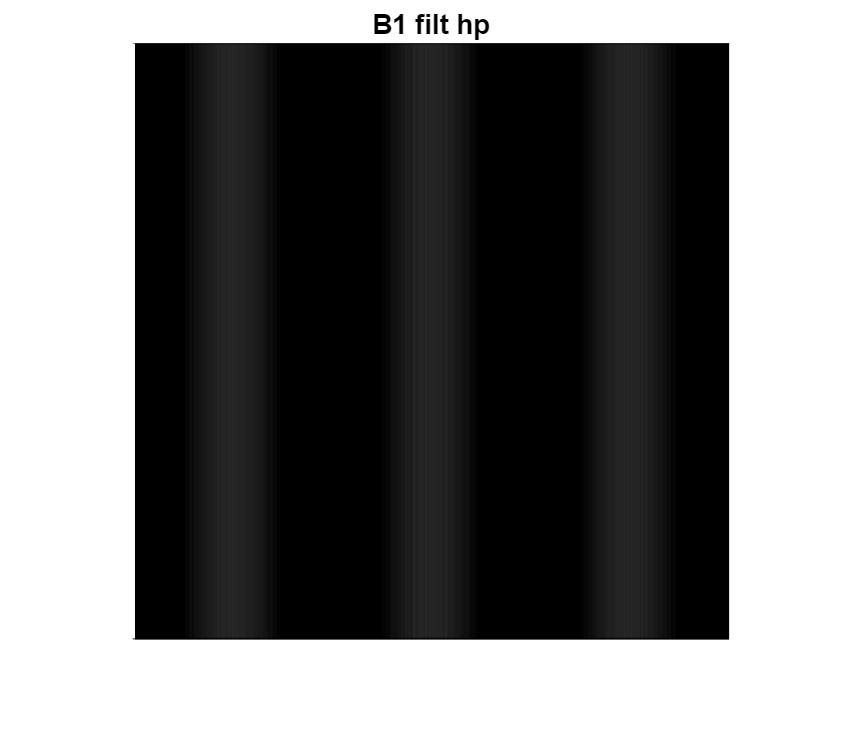

figure(5); imshow(B1_filt_hp); title('B1 filt hp');

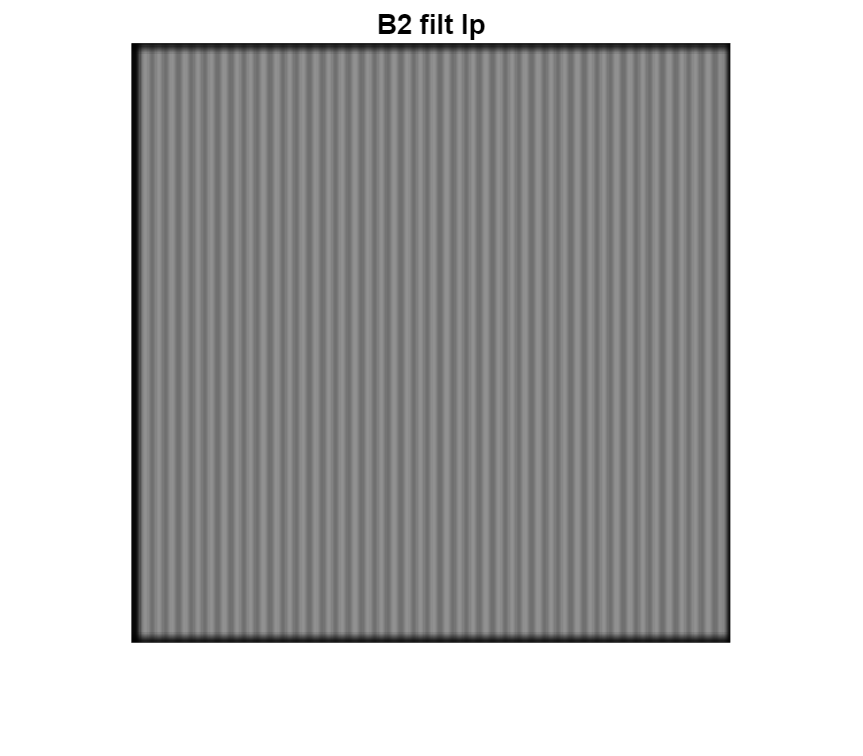


figure(6); imshow(B2_filt_lp); title('B2 filt lp');

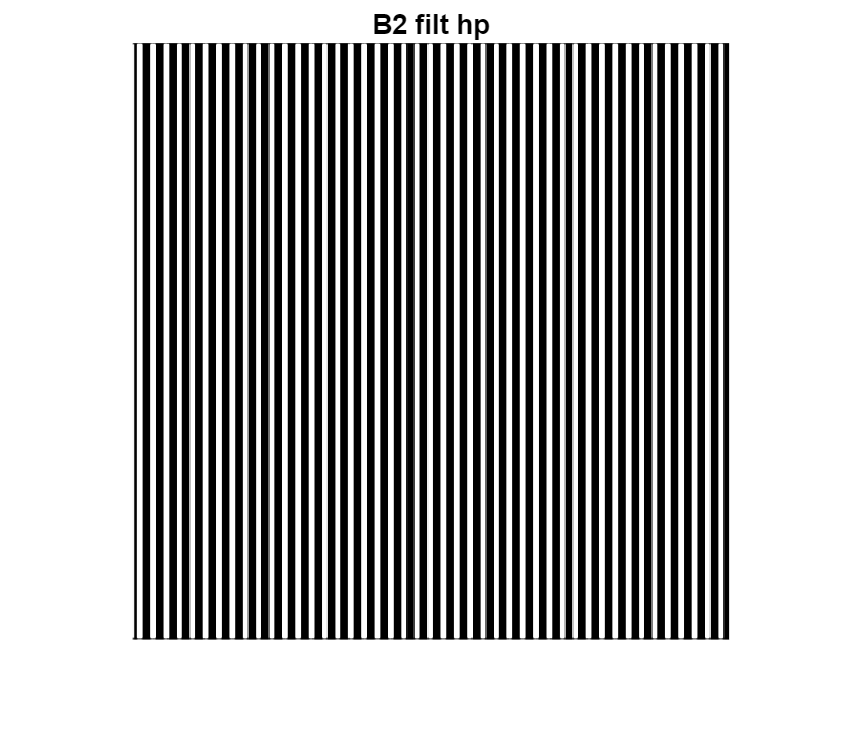

figure(7); imshow(B2_filt_hp); title('B2 filt hp');

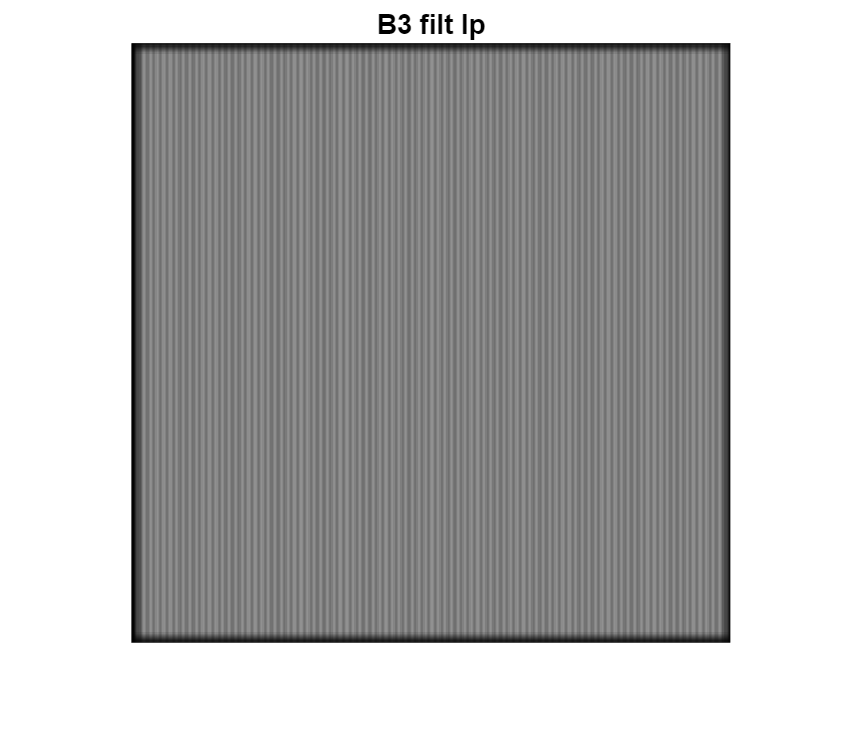


figure(8); imshow(B3_filt_lp); title('B3 filt lp');

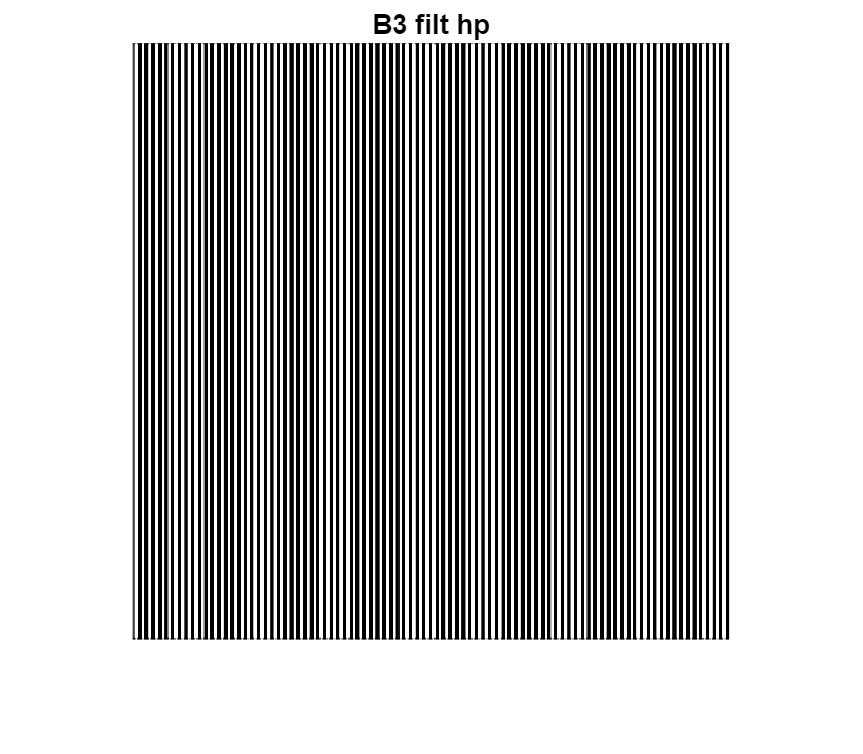

figure(9); imshow(B3_filt_hp); title('B3 filt hp');

uppgift 3)

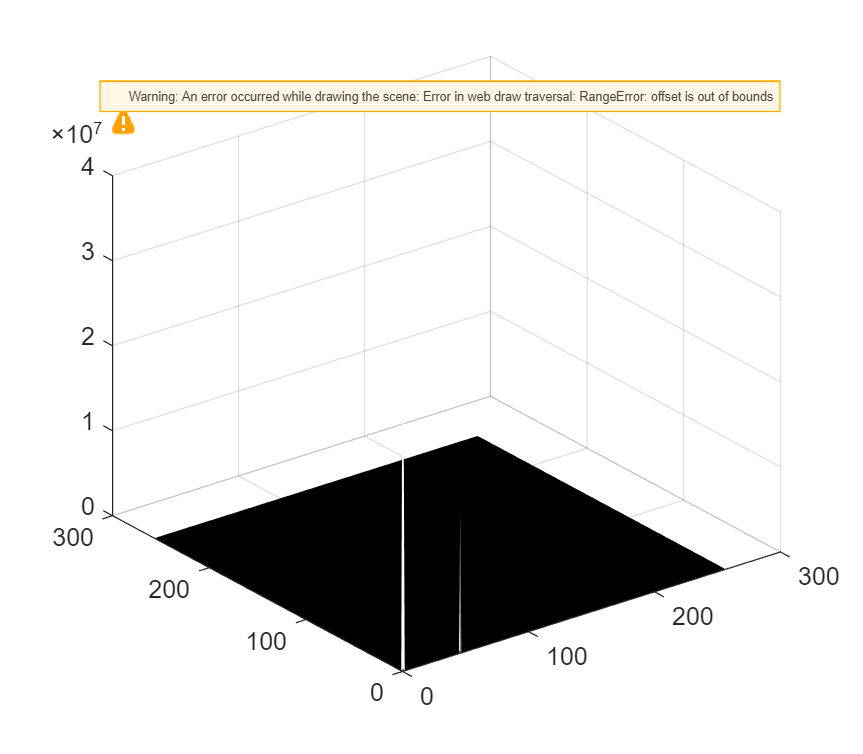

clf

B_frek = fft2(B2);
mesh(abs(B_frek(1:256, 1:256)));

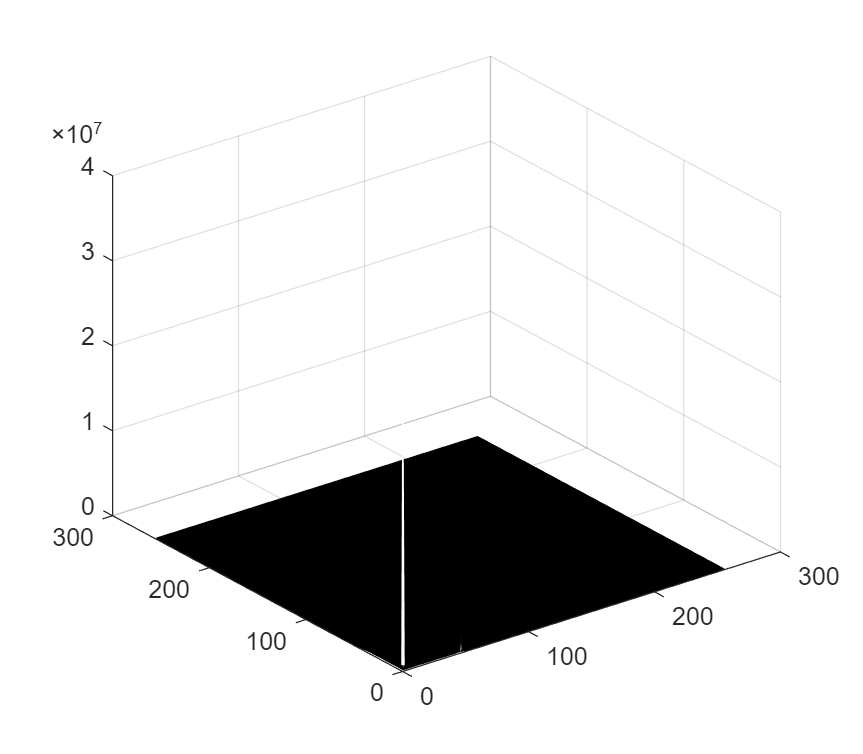



B_lp_frek = fft2(B2_filt_lp);
mesh(abs(B_lp_frek(1:256, 1:256)));

uppgift 4) 

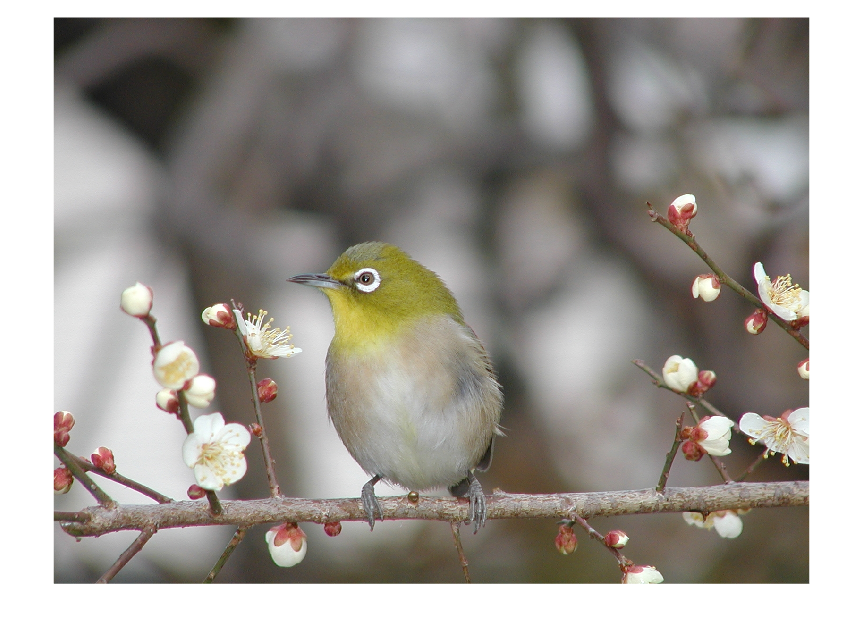

clf

Bird = imread('Bird_lab3.jpg');
imshow(Bird);

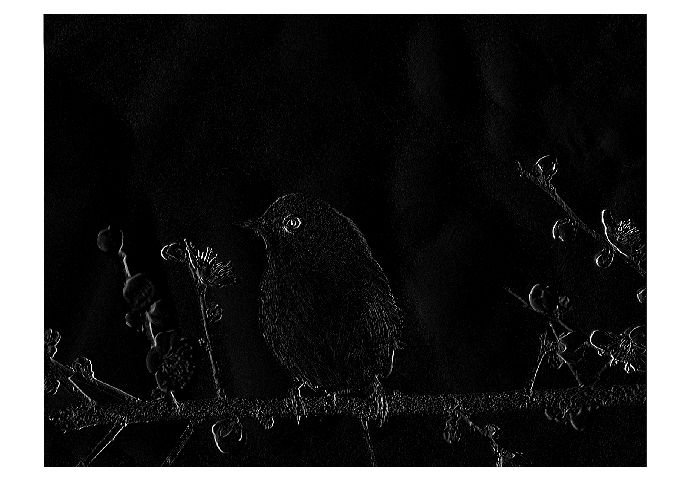

Bird_black = rgb2gray(Bird);

Bird_black_filt_ver = uint8(conv2(single(h_hp),single(Bird_black)));
Bird_black_filt_hor = uint8(conv2(single(transpose(h_hp)),single(Bird_black)));

figure(10); imshow(Bird_black_filt_ver);

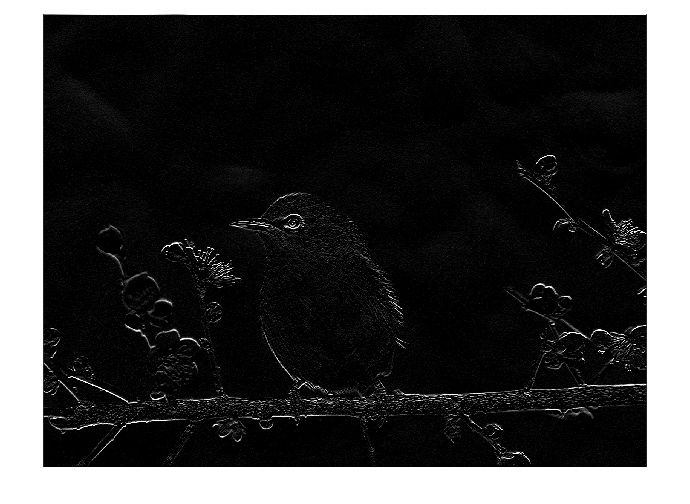

figure(11); imshow(Bird_black_filt_hor);

## Del 2

uppgift 5)

clear 
clf


